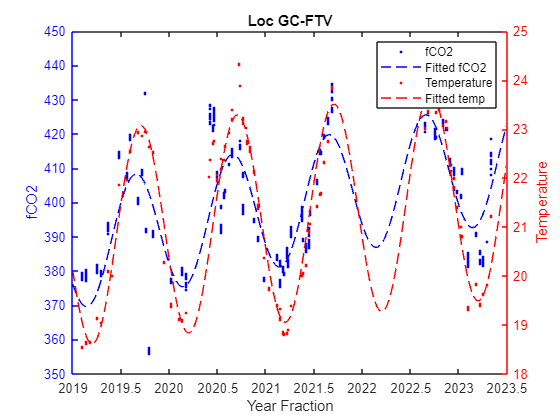

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
title("Loc GC-FTV")
plot(locTLco2.YearFraction, locTLco2.fCO2sw, "b.")
hold on 
plot(fittedCO2, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
title("Loc GC-FTV")
plot(locTLtemp.YearFraction, locTLtemp.IntakeTemp, "r.")
hold on 
plot(fittedTemp, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

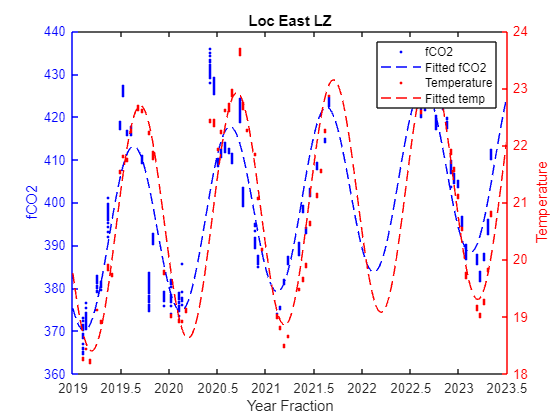

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
title("Loc East LZ")
plot(locLco2.YearFraction, locLco2.fCO2sw, "b.")
hold on 
plot(fittedLCo2, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
title("Loc East LZ")
plot(locLtemp.YearFraction, locLtemp.IntakeTemp, "r.")
hold on 
plot(fittedLtemp, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

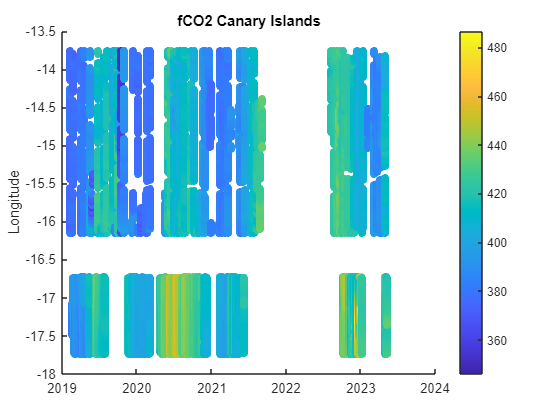

scatter(allTable.YearFraction, allTable.longitude, [], allTable.fCO2sw, "filled")
colorbar;
title("fCO2 Canary Islands")
ylabel("Longitude")

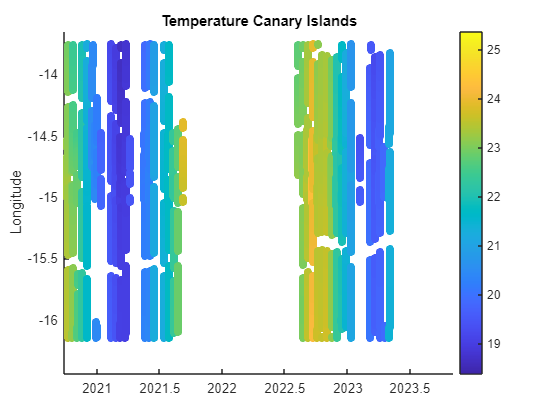

scatter(allTable.YearFraction, allTable.longitude, [], allTable.IntakeTemp, "filled")
colorbar;
title("Temperature Canary Islands")
ylabel("Longitude")

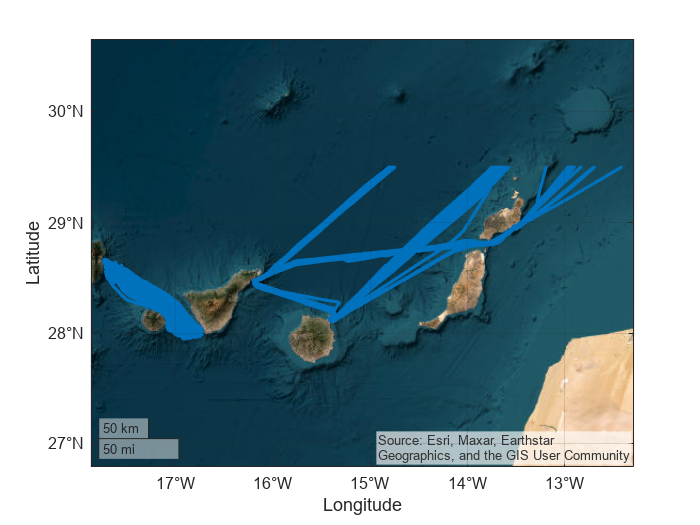

geoplot(allTable.latitude, allTable.longitude, ".")
geobasemap satellite

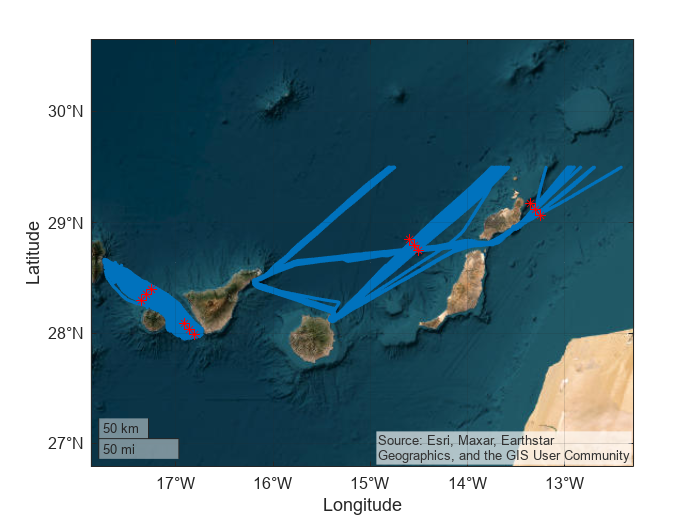

hold on
geoplot([28.35, 28.30, 28.40], [-17.30, -17.35, -17.25], "r*")
hold on
geoplot([28.04, 27.99, 28.09], [-16.86, -16.81, -16.91], "r*")
hold on

geoplot([28.8, 28.85, 28.75], [-14.55, -14.60, -14.50], "r*")
hold on
geoplot([29.12, 29.17, 29.07], [-13.30, -13.35, -13.25], "r*")
hold off